(a) the x[n] is purely real,because $x\left(t\right)\to a_k^* =a_{-k}$


$$\alpha_{-k} =\frac{1}{T}\int x\left(t\right)e^{\mathrm{jk}\omega_0 t} \mathrm{dt}={\left\lbrack \frac{1}{T}\int x\left(t\right)e^{\mathrm{jk}\omega_0 t} \mathrm{dt}\right\rbrack }^* =a_k^*$$


(b) $a_3 =a_{3-5} =a_{-2} =e^{-j\frac{\pi }{4}} ,a_1 =a_{1-5} =a_{-4} =2e^{-j\frac{\pi }{3}}$

a=[1,2*exp(-j*pi/3),exp(j*pi/4),exp(-j*pi/4),2*exp(j*pi/3)]

a =    1.0000 + 0.0000i   1.0000 - 1.7321i   0.7071 + 0.7071i   0.7071 - 0.7071i   1.0000 + 1.7321i


(c)the result of x[n] in one period is [4.414213562373095,2.937213721744947 ,3.200126901447349,-3.562162830049498 ,-1.989391355515894 ],it is totally real numbers .

a=[1,2*exp(-j*pi/3),exp(j*pi/4),exp(-j*pi/4),2*exp(j*pi/3)];
demo=exp(1i*pi/4);
result=zeros(1,5);
for n=0:4
    x=0;
    for k=0:4
    x=x+a(1,k+1)*exp(j*k*2*pi/5*n);
    end
    result(1,n+1)=x;
end
result=real(result)

result =     4.4142    2.9372    3.2001   -3.5622   -1.9894


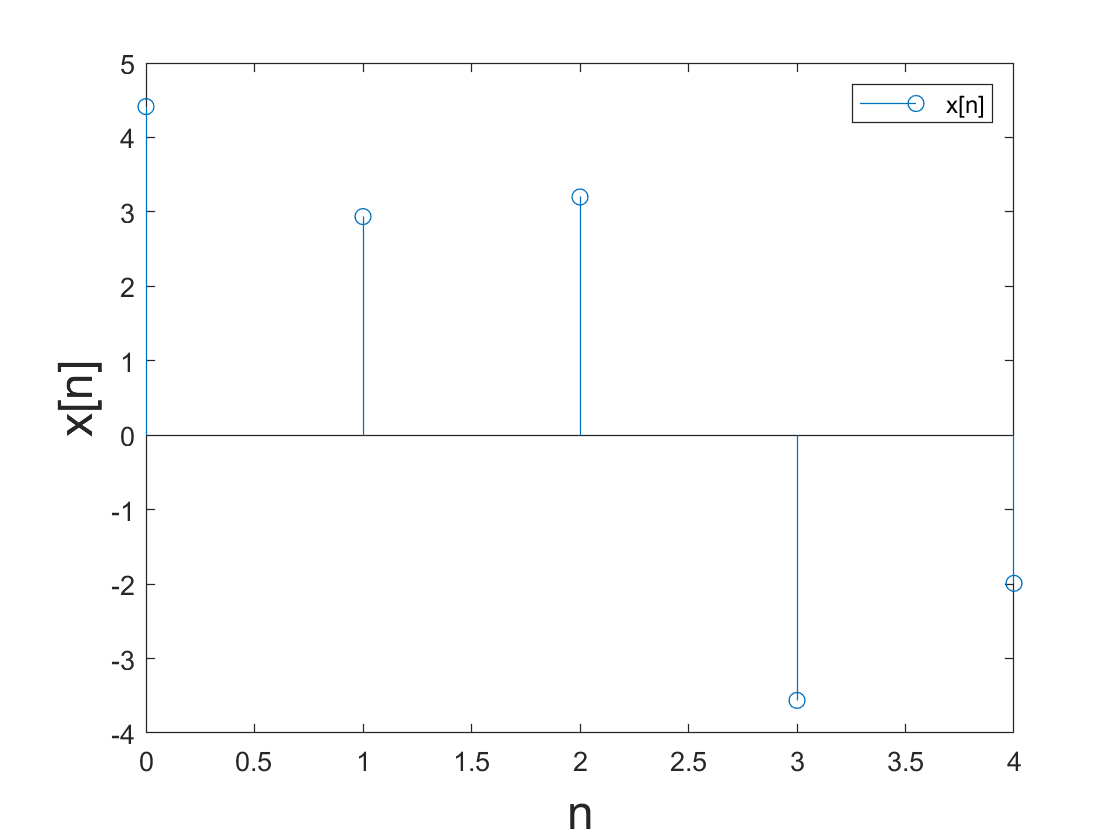

stem(0:4,result);
xlabel('n','Fontsize',18);
ylabel('x[n]','Fontsize',18);legend("x[n]");

(d)

x1=ones(1,8);
x2=[x1,zeros(1,8)];
x3=[x1,zeros(1,24)]

x3 =      1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


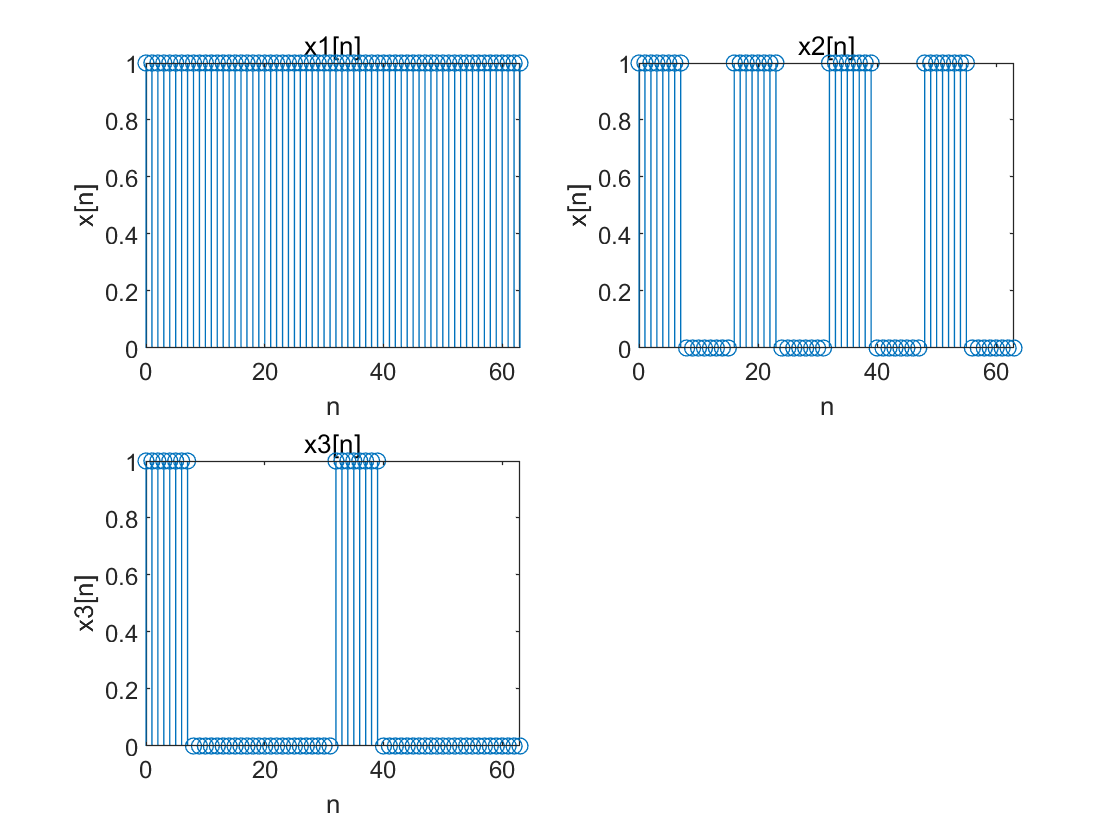

subplot(2, 2, 1);
stem(0:63,[x1 x1 x1 x1 x1 x1 x1 x1]);
xlabel('n','Fontsize',6);
ylabel('x[n]','Fontsize',6);
title("x1[n]");


subplot(2, 2, 2);
stem(0:63,[x2 x2 x2 x2 ]);
xlabel('n','Fontsize',6);
ylabel('x[n]','Fontsize',6);
title("x2[n]");

subplot(2, 2, 3);
stem(0:63,[x3 x3]);
xlabel('n','Fontsize',6);
ylabel('x3[n]','Fontsize',6);
title("x3[n]");

(e)according to the EQ.(3.2),the result is 1,0.5,0.25 which are totally same as the figure's results.

x1=ones(1,8);
x2=[x1,zeros(1,8)];
x3=[x1,zeros(1,24)]

x3 =      1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


a1=1/8*fft(x1)

a1 =      1     0     0     0     0     0     0     0


a2=1/16*fft(x2);
a3=1/32*fft(x3)

a3 =    0.2500 + 0.0000i   0.1743 - 0.1430i   0.0313 - 0.1571i  -0.0359 - 0.0671i   0.0000 + 0.0000i   0.0449 - 0.0136i   0.0313 - 0.0468i  -0.0034 - 0.0347i   0.0000 + 0.0000i   0.0284 + 0.0028i   0.0313 - 0.0209i   0.0073 - 0.0240i   0.0000 + 0.0000i   0.0204 + 0.0109i   0.0313 - 0.0062i   0.0141 - 0.0172i   0.0000 + 0.0000i   0.0141 + 0.0172i   0.0313 + 0.0062i   0.0204 - 0.0109i   0.0000 + 0.0000i   0.0073 + 0.0240i   0.0313 + 0.0209i   0.0284 - 0.0028i   0.0000 + 0.0000i  -0.0034 + 0.0347i   0.0313 + 0.0468i   0.0449 + 0.0136i   0.0000 + 0.0000i  -0.0359 + 0.0671i   0.0313 + 0.1571i   0.1743 + 0.1430i


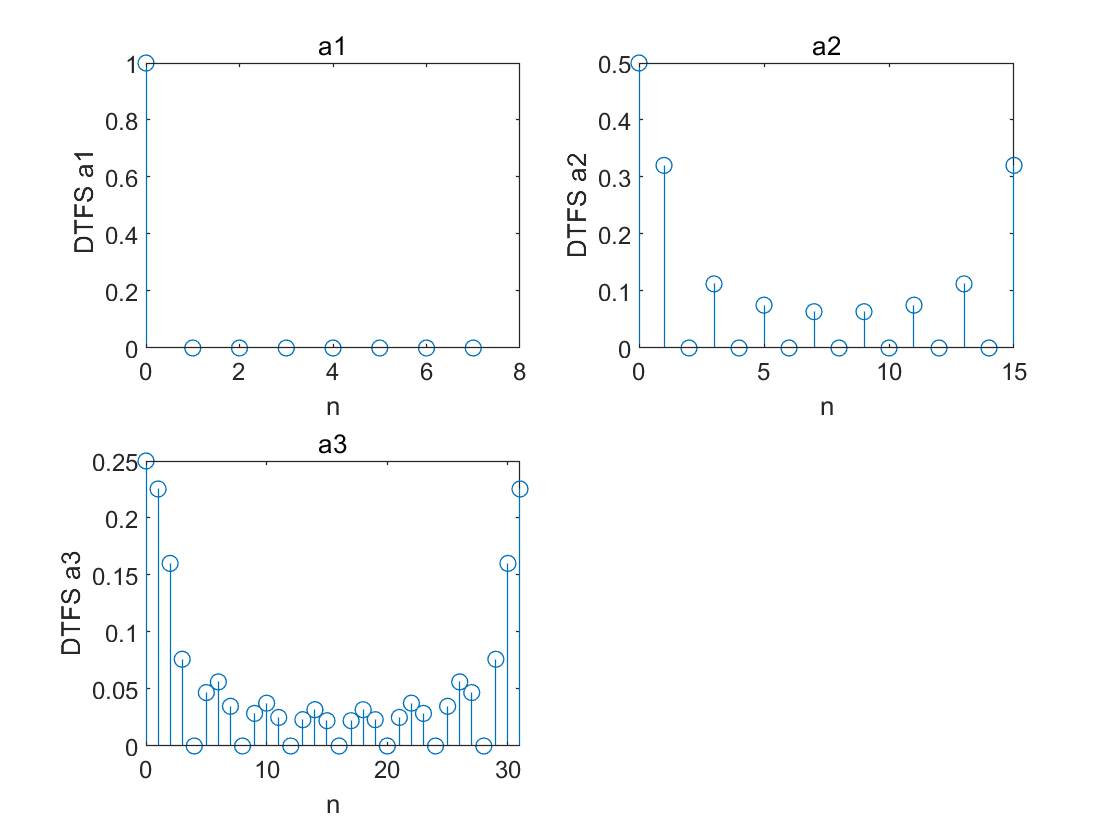

stem(0:7,abs(a1))

subplot(2, 2, 1);
stem(0:7,abs(a1));
xlabel('n','Fontsize',6);
ylabel(' DTFS a1','Fontsize',6);
title("a1");


subplot(2, 2, 2);
stem(0:15,abs(a2));
xlabel('n','Fontsize',6);
ylabel('DTFS a2','Fontsize',6);
title("a2");

subplot(2, 2, 3);
stem(0:31,abs(a3));
xlabel('n','Fontsize',6);
ylabel('DTFS a3','Fontsize',6);
title("a3");

(f)

x1=ones(1,8);
x2=[x1,zeros(1,8)];
x3=[x1,zeros(1,24)];
a1=1/8*fft(x1);
a2=1/16*fft(x2);
a3=1/32*fft(x3);
x3_2=zeros(1,32);
for n=0:31
    Demo=0;
    for k=-2:2
    Demo=Demo+a3(1,mod((k+32),32)+1)*exp(j*k*n*2*pi/32);
    end
x3_2(1,n+1)=Demo;
end
x3_2=real(x3_2)

x3_2 =     0.6610    0.8256    0.9478    1.0129    1.0129    0.9478    0.8256    0.6610    0.4735    0.2846    0.1145   -0.0200   -0.1084   -0.1473   -0.1405   -0.0985   -0.0360    0.0303    0.0849    0.1155    0.1155    0.0849    0.0303   -0.0360   -0.0985   -0.1405   -0.1473   -0.1084   -0.0200    0.1145    0.2846    0.4735






x3_8=zeros(1,32);
for n=0:31
    Demo=0;
    for k=-8:8
    Demo=Demo+a3(1,mod((k+32),32)+1)*exp(j*k*n*2*pi/32);
    end
x3_8(1,n+1)=Demo;
end
x3_8=real(x3_8)

x3_8 =     0.7347    1.0900    1.0900    0.9285    0.9285    1.0900    1.0900    0.7347    0.2347   -0.0570   -0.0570    0.0293    0.0293   -0.0197   -0.0197    0.0153    0.0153   -0.0134   -0.0134    0.0128    0.0128   -0.0134   -0.0134    0.0153    0.0153   -0.0197   -0.0197    0.0293    0.0293   -0.0570   -0.0570    0.2347





x3_12=zeros(1,32);
for n=0:31
    Demo=0;
    for k=-12:12
    Demo=Demo+a3(1,mod((k+32),32)+1)*exp(j*k*n*2*pi/32);
    end
x3_12(1,n+1)=Demo;
end
x3_12=real(x3_12)

x3_12 =     0.8686    1.1199    0.9160    1.0302    1.0302    0.9160    1.1199    0.8686    0.1186   -0.0876    0.0486   -0.0124   -0.0124    0.0222   -0.0183    0.0064    0.0064   -0.0139    0.0132   -0.0053   -0.0053    0.0132   -0.0139    0.0064    0.0064   -0.0183    0.0222   -0.0124   -0.0124    0.0486   -0.0876    0.1186




x3_all=zeros(1,32);
for n=0:31
    Demo=0;
    for k=-15:16
    Demo=Demo+a3(1,mod((k+32),32)+1)*exp(j*k*n*2*pi/32);
    end
x3_all(1,n+1)=Demo;
end
x3_all=real(x3_all)

x3_all =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000


(g)理论题暂空缺

(h)according to the figures x3_all equals to the x3. This signal doesn't show Gibbs  phenomenon

x1=ones(1,8);
x2=[x1,zeros(1,8)];
x3=[x1,zeros(1,24)];
a1=1/8*fft(x1);
a2=1/16*fft(x2);
a3=1/32*fft(x3);
x3_2=zeros(1,32);
for n=0:31
    Demo=0;
    for k=-2:2
    Demo=Demo+a3(1,mod((k+32),32)+1)*exp(j*k*n*2*pi/32);
    end
x3_2(1,n+1)=Demo;
end
x3_2=real(x3_2)

x3_2 =     0.6610    0.8256    0.9478    1.0129    1.0129    0.9478    0.8256    0.6610    0.4735    0.2846    0.1145   -0.0200   -0.1084   -0.1473   -0.1405   -0.0985   -0.0360    0.0303    0.0849    0.1155    0.1155    0.0849    0.0303   -0.0360   -0.0985   -0.1405   -0.1473   -0.1084   -0.0200    0.1145    0.2846    0.4735






x3_8=zeros(1,32);
for n=0:31
    Demo=0;
    for k=-8:8
    Demo=Demo+a3(1,mod((k+32),32)+1)*exp(j*k*n*2*pi/32);
    end
x3_8(1,n+1)=Demo;
end
x3_8=real(x3_8)

x3_8 =     0.7347    1.0900    1.0900    0.9285    0.9285    1.0900    1.0900    0.7347    0.2347   -0.0570   -0.0570    0.0293    0.0293   -0.0197   -0.0197    0.0153    0.0153   -0.0134   -0.0134    0.0128    0.0128   -0.0134   -0.0134    0.0153    0.0153   -0.0197   -0.0197    0.0293    0.0293   -0.0570   -0.0570    0.2347





x3_12=zeros(1,32);
for n=0:31
    Demo=0;
    for k=-12:12
    Demo=Demo+a3(1,mod((k+32),32)+1)*exp(j*k*n*2*pi/32);
    end
x3_12(1,n+1)=Demo;
end
x3_12=real(x3_12)

x3_12 =     0.8686    1.1199    0.9160    1.0302    1.0302    0.9160    1.1199    0.8686    0.1186   -0.0876    0.0486   -0.0124   -0.0124    0.0222   -0.0183    0.0064    0.0064   -0.0139    0.0132   -0.0053   -0.0053    0.0132   -0.0139    0.0064    0.0064   -0.0183    0.0222   -0.0124   -0.0124    0.0486   -0.0876    0.1186




x3_all=zeros(1,32);
for n=0:31
    Demo=0;
    for k=-15:16
    Demo=Demo+a3(1,mod((k+32),32)+1)*exp(j*k*n*2*pi/32);
    end
x3_all(1,n+1)=Demo;
end
x3_all=real(x3_all)

x3_all =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000


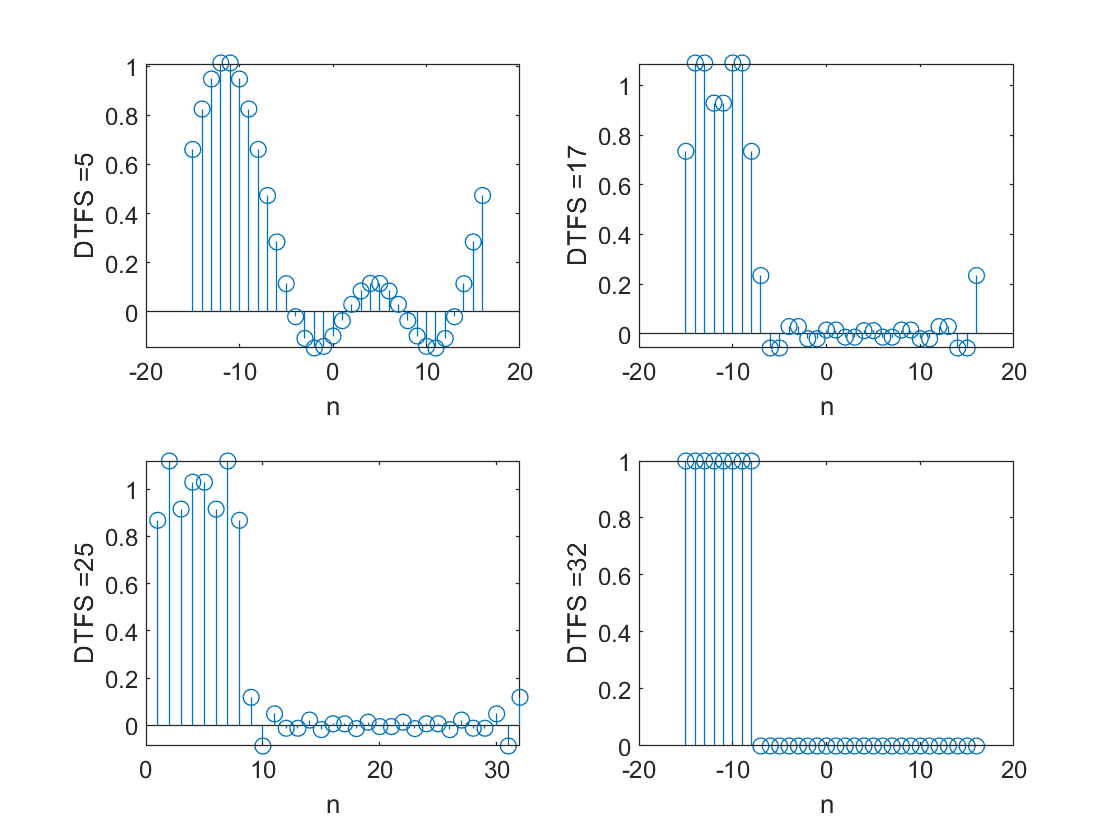

subplot(2, 2, 1);
stem(-15:16,x3_2);
xlabel('n','Fontsize',6);
ylabel('DTFS =5','Fontsize',6);
subplot(2, 2, 2);
stem(-15:16,x3_8);
xlabel('n','Fontsize',6);
ylabel('DTFS =17','Fontsize',6);

subplot(2, 2, 3);
stem(x3_12);
xlabel('n','Fontsize',6);
ylabel('DTFS =25','Fontsize',6);
subplot(2, 2, 4);
stem(-15:16,x3_all);

xlabel('n','Fontsize',6);
ylabel('DTFS =32','Fontsize',6);